This script is for sleep deprivation (SD) analysis. Usually for sleep deprivation experiments, there will be 4 hours of recording with FLP (pre-SD, ) and another 4 or 5 hours recording with EEG/EMG video recording only.

The 1st session is for analyze the FLP recording on a hour by hour basis.

After turning the MATLAB into the FLP analysis mode:

preSDfile='continuous aquistion data_7.mat';
FirstHourSDfile='continuous aquistion data_8.mat';
SixthHourSDfile='continuous aquistion data_9.mat';
postSDfile='continuous aquistion data_10.mat';
timebin = 1;
ch=1;

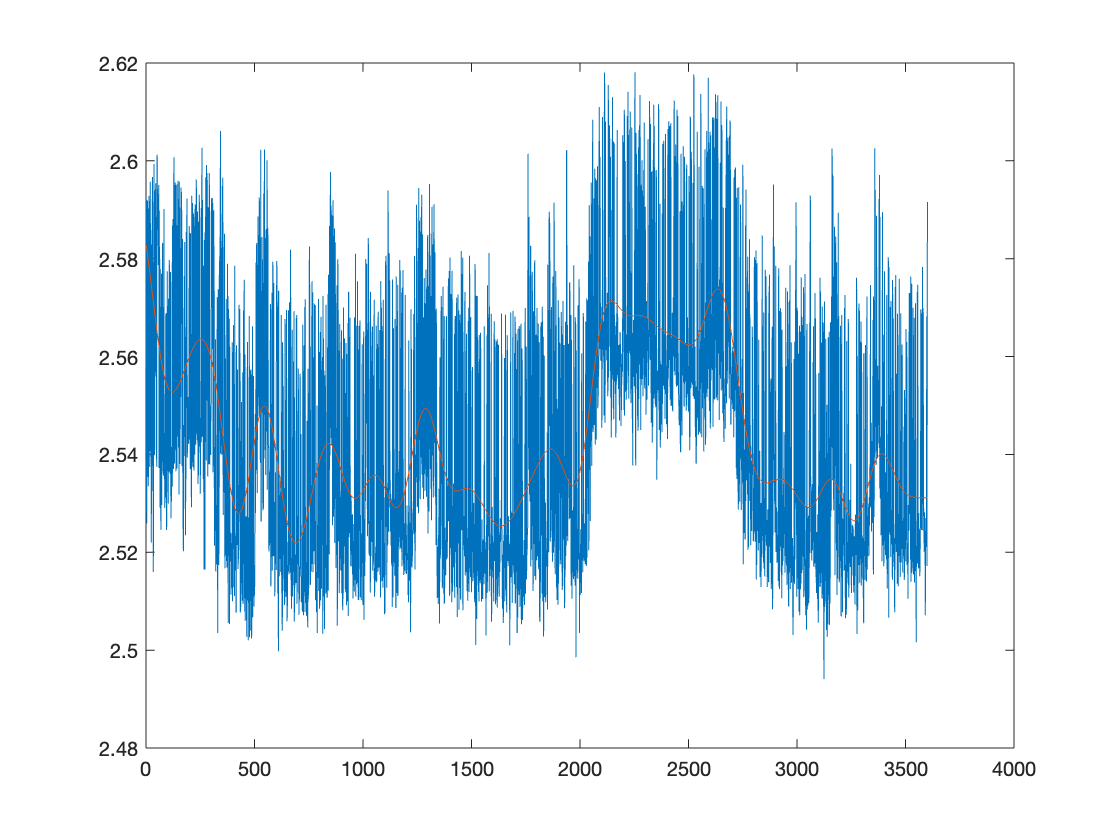


load(preSDfile);
filename='preSD.mat';

FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename);

load(filename)

time(isnan(time))=[];
photoncount(isnan(photoncount))=[];
tau_avg(isnan(tau_avg))=[];
tau_avgTrunc(isnan(tau_avgTrunc))=[];
tau_empTrunc(isnan(tau_empTrunc))=[];
p1(isnan(p1))=[];
chi2(isnan(chi2))=[];

save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

preSD_tau_empTrunc=tau_empTrunc;
preSD_photoncount=photoncount;
preSD_time=time;

signal_to_filter=tau_empTrunc;

order=6;
Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
CutoffLow=0.005;
normalizedCutoffLow = CutoffLow / Nyquist;
[b1,a1]=butter(order,normalizedCutoffLow,'low');
preSD_tau_empTrunc_DC=filtfilt(b1,a1,signal_to_filter);

figure
plot(time, signal_to_filter);
hold on
plot(time, preSD_tau_empTrunc_DC);

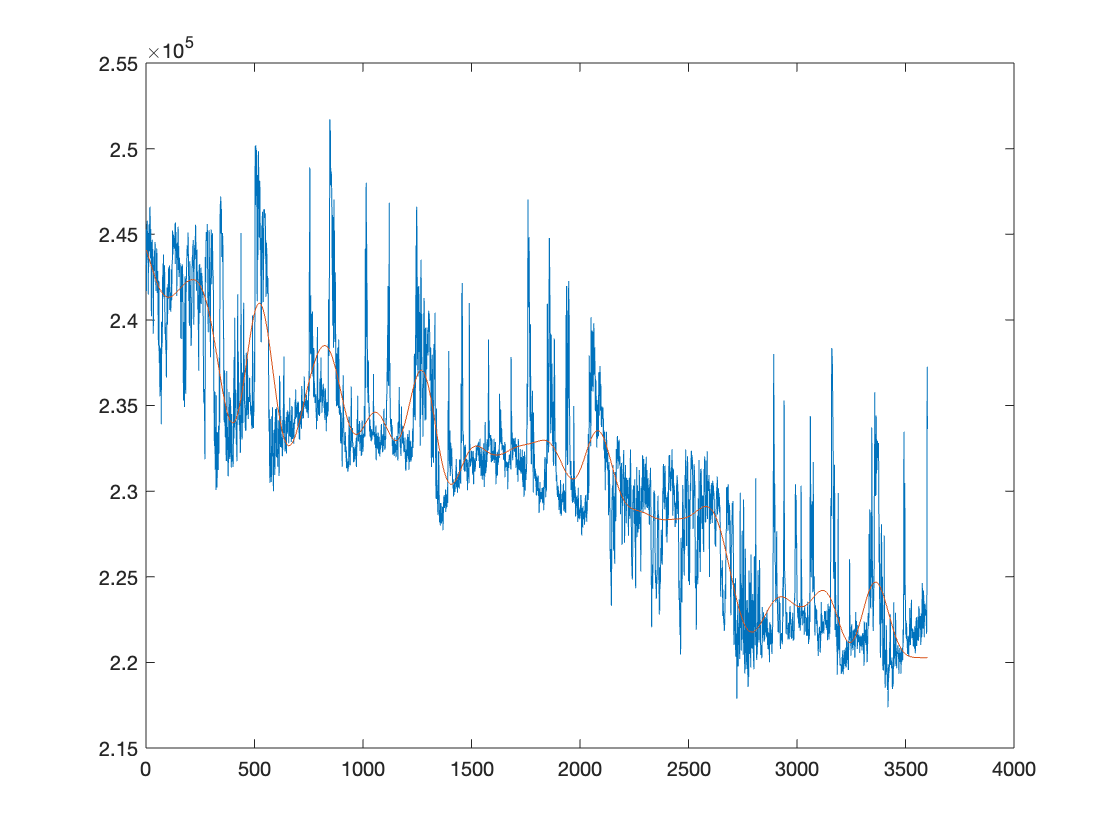



CutoffHigh=0.01;
normalizedCutoffHigh = CutoffHigh / Nyquist;
[b2,a2]=butter(order,normalizedCutoffHigh,'high');
preSD_tau_empTrunc_AC=filtfilt(b2,a2,signal_to_filter);

% figure
% yyaxis left
% plot(time, signal_to_filter);
% yyaxis right
% hold on
% plot(time, preSD_tau_empTrunc_AC);

signal_to_filter=photoncount;

order=6;
Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
CutoffLow=0.005;
normalizedCutoffLow = CutoffLow / Nyquist;
[b1,a1]=butter(order,normalizedCutoffLow,'low');
preSD_photoncount_DC=filtfilt(b1,a1,signal_to_filter);

figure
plot(time, signal_to_filter);
hold on
plot(time, preSD_photoncount_DC);



CutoffHigh=0.01;
normalizedCutoffHigh = CutoffHigh / Nyquist;
[b2,a2]=butter(order,normalizedCutoffHigh,'high');
preSD_photoncount_AC=filtfilt(b2,a2,signal_to_filter);



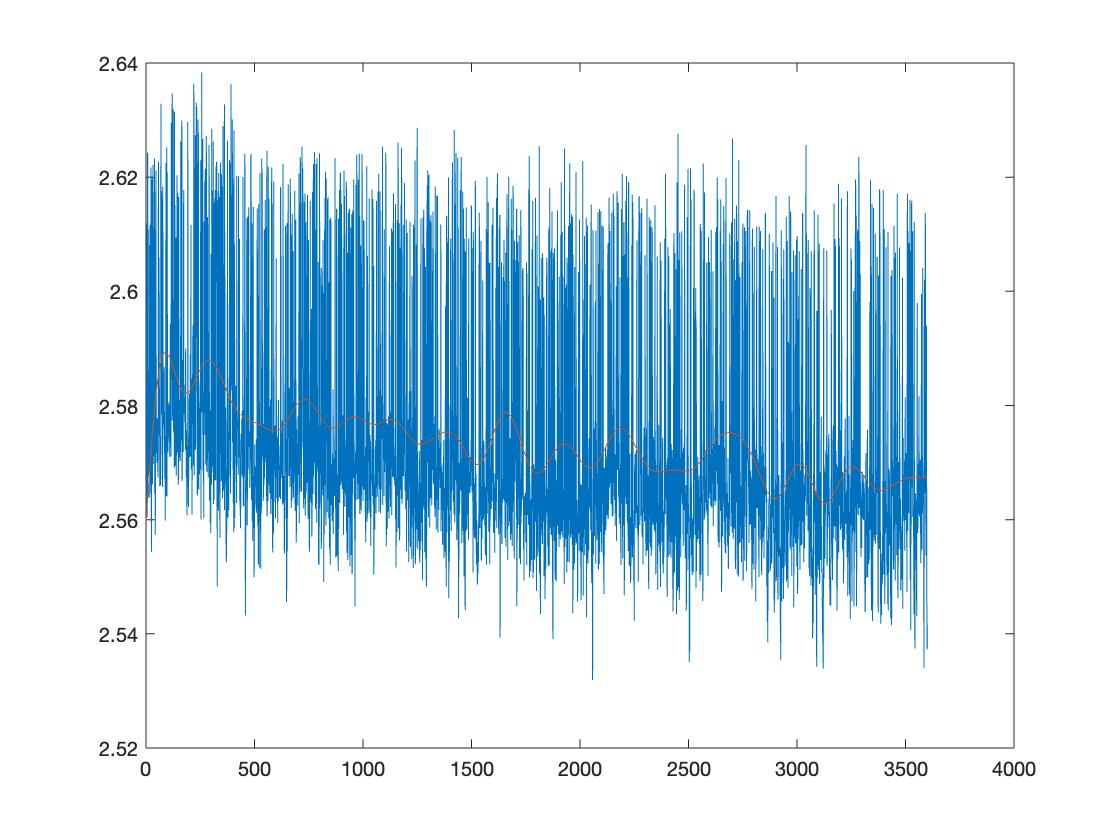

load(FirstHourSDfile);
filename='1stHourSD.mat';

FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename);

load(filename)

time(isnan(time))=[];
photoncount(isnan(photoncount))=[];
tau_avg(isnan(tau_avg))=[];
tau_avgTrunc(isnan(tau_avgTrunc))=[];
tau_empTrunc(isnan(tau_empTrunc))=[];
p1(isnan(p1))=[];
chi2(isnan(chi2))=[];

save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

FirstHour_tau_empTrunc=tau_empTrunc;
FirstHour_photoncount=photoncount;
FirstHour_time=time;

signal_to_filter=tau_empTrunc;

order=6;
Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
CutoffLow=0.005;
normalizedCutoffLow = CutoffLow / Nyquist;
[b1,a1]=butter(order,normalizedCutoffLow,'low');
FirstHour_tau_empTrunc_DC=filtfilt(b1,a1,signal_to_filter);

figure
plot(time, signal_to_filter);
hold on
plot(time, FirstHour_tau_empTrunc_DC);

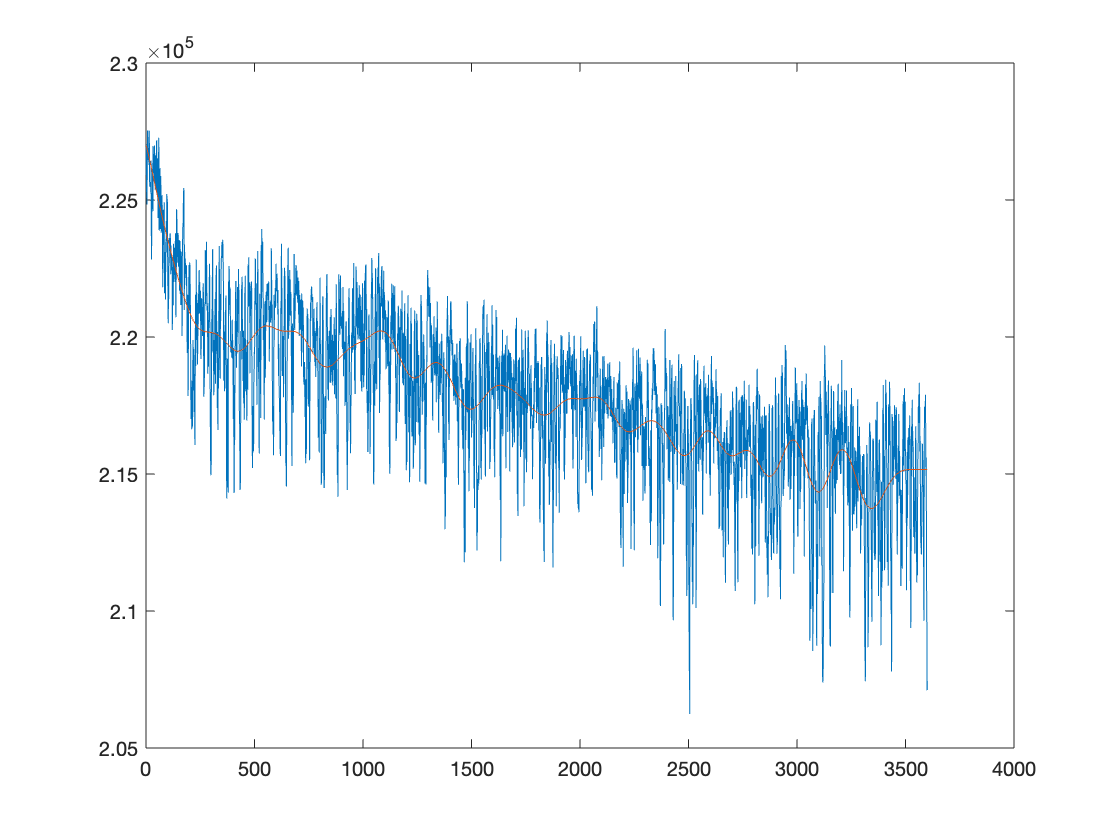



CutoffHigh=0.01;
normalizedCutoffHigh = CutoffHigh / Nyquist;
[b2,a2]=butter(order,normalizedCutoffHigh,'high');
FirstHour_tau_empTrunc_AC=filtfilt(b2,a2,signal_to_filter);

% figure
% yyaxis left
% plot(time, signal_to_filter);
% yyaxis right
% hold on
% plot(time, FirstHour_tau_empTrunc_AC);
signal_to_filter=photoncount;

order=6;
Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
CutoffLow=0.005;
normalizedCutoffLow = CutoffLow / Nyquist;
[b1,a1]=butter(order,normalizedCutoffLow,'low');
FirstHour_photoncount_DC=filtfilt(b1,a1,signal_to_filter);

figure
plot(time, signal_to_filter);
hold on
plot(time, FirstHour_photoncount_DC);



CutoffHigh=0.01;
normalizedCutoffHigh = CutoffHigh / Nyquist;
[b2,a2]=butter(order,normalizedCutoffHigh,'high');
FirstHour_photoncount_AC=filtfilt(b2,a2,signal_to_filter);


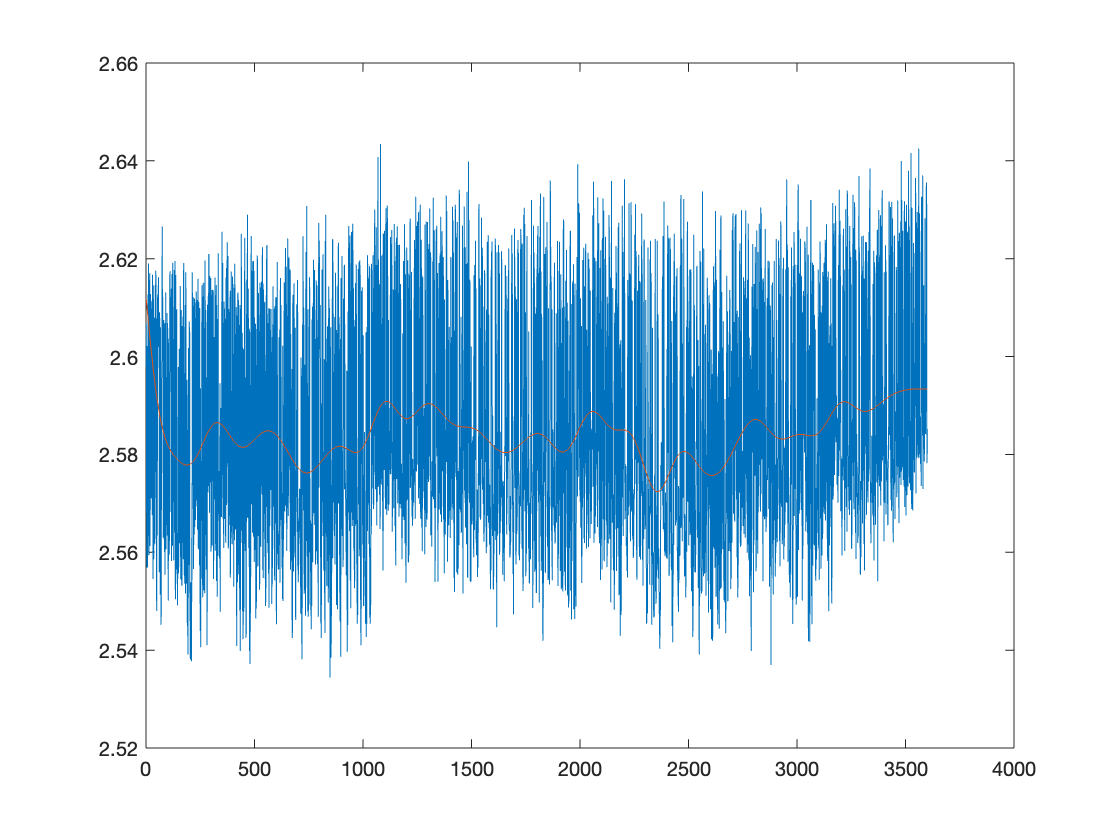

load(SixthHourSDfile);
filename='6thHourSD.mat';

FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename);

load(filename)

time(isnan(time))=[];
photoncount(isnan(photoncount))=[];
tau_avg(isnan(tau_avg))=[];
tau_avgTrunc(isnan(tau_avgTrunc))=[];
tau_empTrunc(isnan(tau_empTrunc))=[];
p1(isnan(p1))=[];
chi2(isnan(chi2))=[];

save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

SixthHour_tau_empTrunc=tau_empTrunc;
SixthHour_photoncount=photoncount;
SixthHour_time=time;

signal_to_filter=tau_empTrunc;

order=6;
Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
CutoffLow=0.005;
normalizedCutoffLow = CutoffLow / Nyquist;
[b1,a1]=butter(order,normalizedCutoffLow,'low');
SixthHour_tau_empTrunc_DC=filtfilt(b1,a1,signal_to_filter);

figure
plot(time, signal_to_filter);
hold on
plot(time, SixthHour_tau_empTrunc_DC);

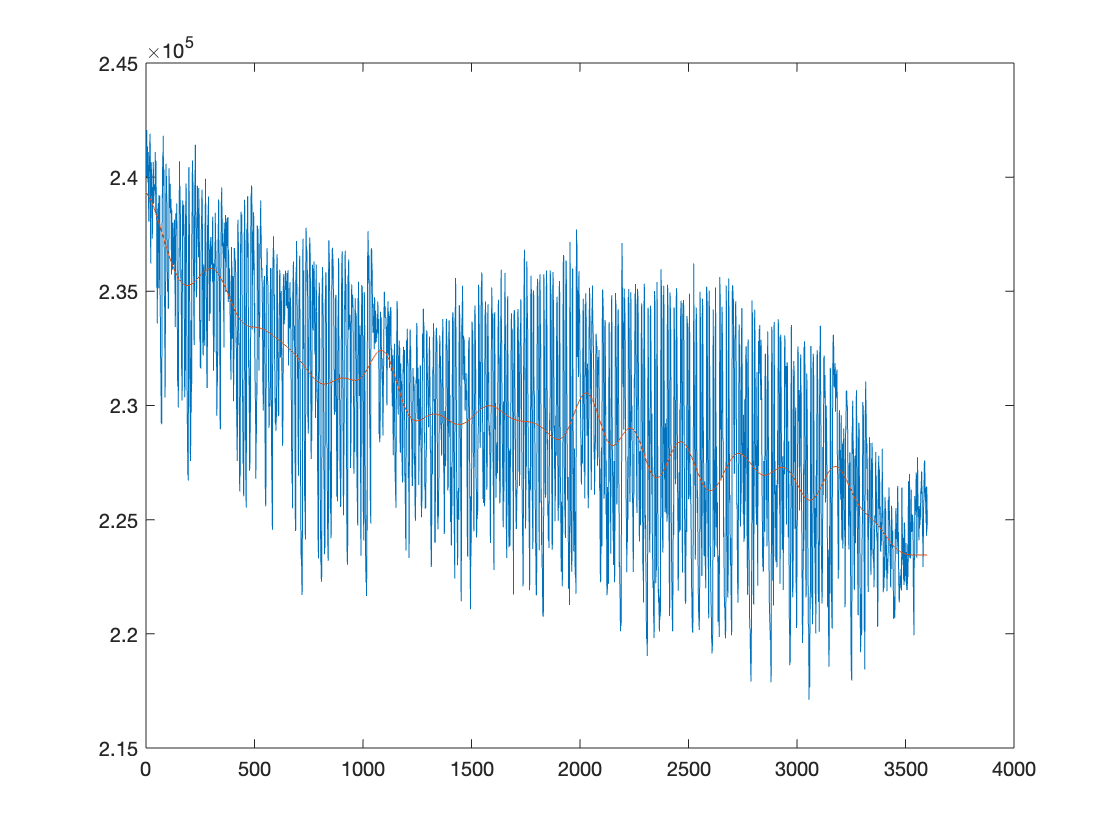



CutoffHigh=0.01;
normalizedCutoffHigh = CutoffHigh / Nyquist;
[b2,a2]=butter(order,normalizedCutoffHigh,'high');
SixthHour_tau_empTrunc_AC=filtfilt(b2,a2,signal_to_filter);

% figure
% yyaxis left
% plot(time, signal_to_filter);
% yyaxis right
% hold on
% plot(time, SixthHour_tau_empTrunc_AC);
signal_to_filter=photoncount;

order=6;
Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
CutoffLow=0.005;
normalizedCutoffLow = CutoffLow / Nyquist;
[b1,a1]=butter(order,normalizedCutoffLow,'low');
SixthHour_photoncount_DC=filtfilt(b1,a1,signal_to_filter);

figure
plot(time, signal_to_filter);
hold on
plot(time, SixthHour_photoncount_DC);



CutoffHigh=0.01;
normalizedCutoffHigh = CutoffHigh / Nyquist;
[b2,a2]=butter(order,normalizedCutoffHigh,'high');
SixthHour_photoncount_AC=filtfilt(b2,a2,signal_to_filter);


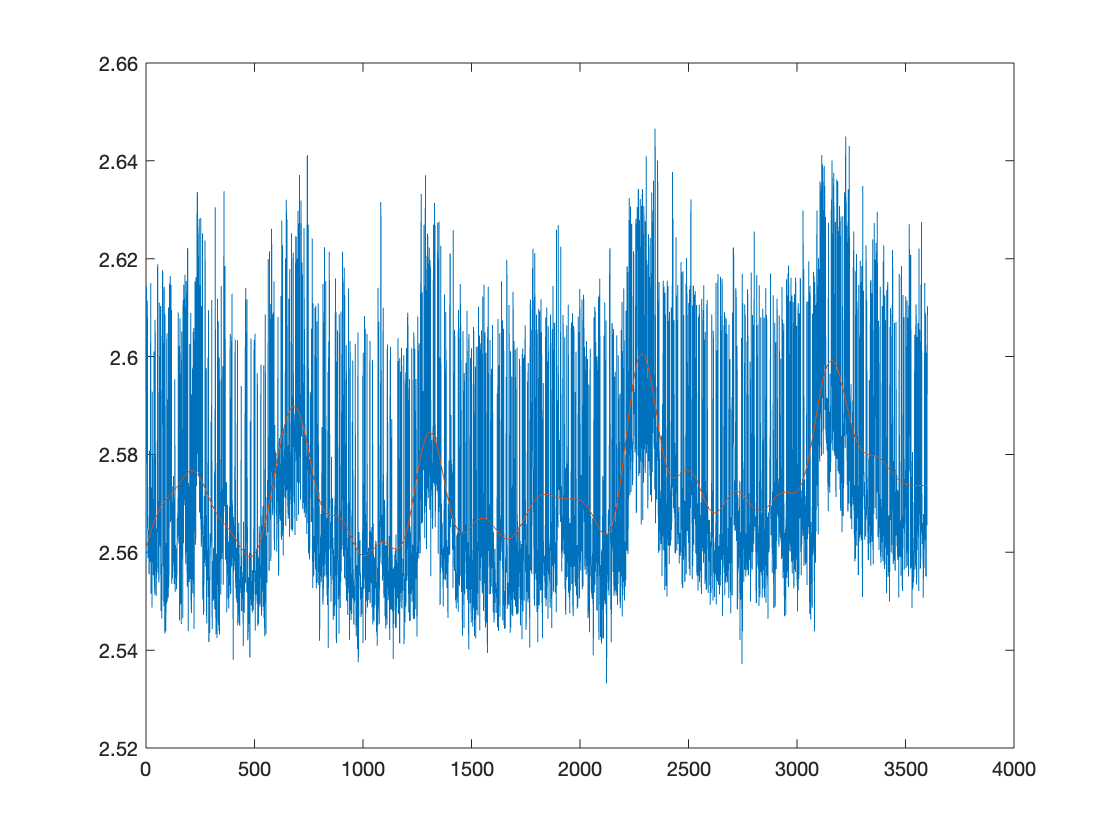

load(postSDfile);
filename='postSD.mat';

FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename);

load(filename)

time(isnan(time))=[];
photoncount(isnan(photoncount))=[];
tau_avg(isnan(tau_avg))=[];
tau_avgTrunc(isnan(tau_avgTrunc))=[];
tau_empTrunc(isnan(tau_empTrunc))=[];
p1(isnan(p1))=[];
chi2(isnan(chi2))=[];

save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2');


postSD_tau_empTrunc=tau_empTrunc;
postSD_photoncount=photoncount;
postSD_time=time;

signal_to_filter=tau_empTrunc;

order=6;
Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
CutoffLow=0.005;
normalizedCutoffLow = CutoffLow / Nyquist;
[b1,a1]=butter(order,normalizedCutoffLow,'low');
postSD_tau_empTrunc_DC=filtfilt(b1,a1,signal_to_filter);

figure
plot(time, signal_to_filter);
hold on
plot(time, postSD_tau_empTrunc_DC);

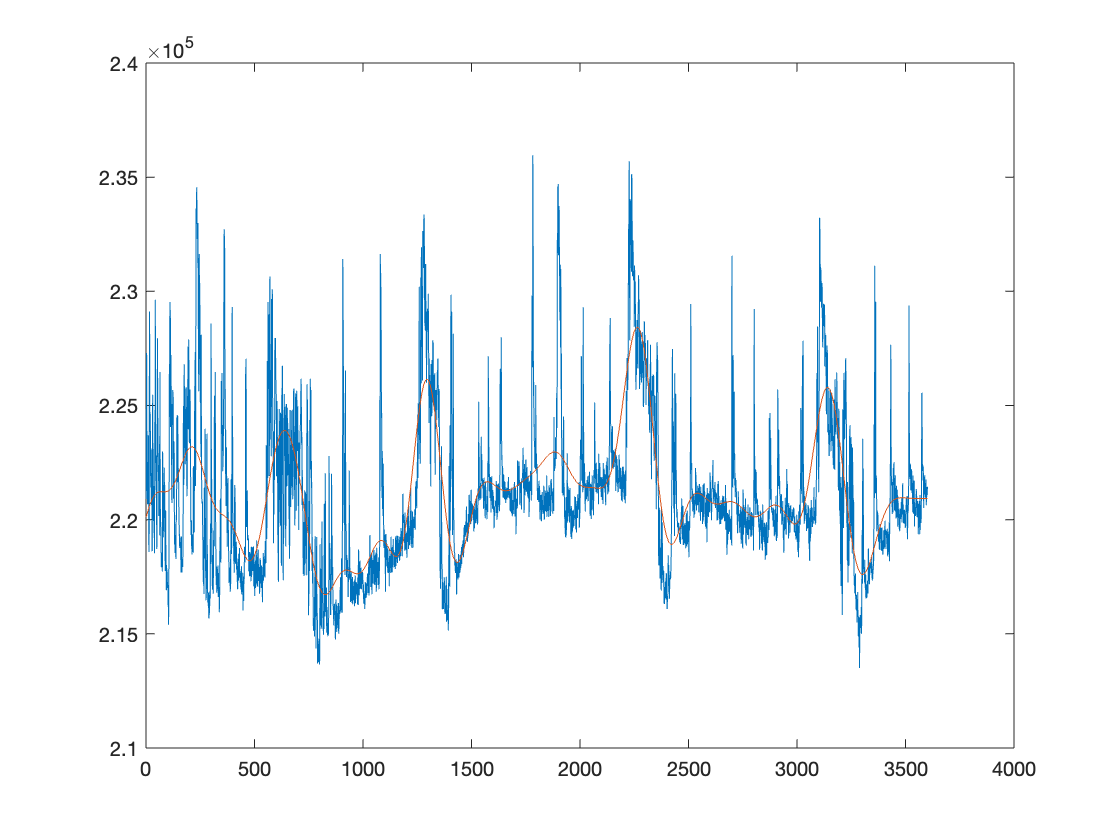



CutoffHigh=0.01;
normalizedCutoffHigh = CutoffHigh / Nyquist;
[b2,a2]=butter(order,normalizedCutoffHigh,'high');
postSD_tau_empTrunc_AC=filtfilt(b2,a2,signal_to_filter);

% figure
% yyaxis left
% plot(time, signal_to_filter);
% yyaxis right
% hold on
% plot(time, postSD_tau_empTrunc_AC);

signal_to_filter=photoncount;

order=6;
Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
CutoffLow=0.005;
normalizedCutoffLow = CutoffLow / Nyquist;
[b1,a1]=butter(order,normalizedCutoffLow,'low');
postSD_photoncount_DC=filtfilt(b1,a1,signal_to_filter);

figure
plot(time, signal_to_filter);
hold on
plot(time, postSD_photoncount_DC);



CutoffHigh=0.01;
normalizedCutoffHigh = CutoffHigh / Nyquist;
[b2,a2]=butter(order,normalizedCutoffHigh,'high');
postSD_photoncount_AC=filtfilt(b2,a2,signal_to_filter);

Next session is to import the sleep states data from sleep scoring. There will be 3 types of format to show the sleep states in MATLAB. 1st is a 900 long numberic serie of the sleep states. 2nd is a 3600 long numberic serie indicating in each second of the hour what state the mouse is in. 3rd is a serie of numbers that correspond to each data point of the FLP recording.

% This is the 1st format, a 900 long number serie, called states_#h.
for i=1:8 % Depending on how many acquistions we have from sleep scoring
    
    states=readNPY(['StatesAcq',num2str(i+6),'_hr0.npy']);
    eval(['states_',num2str(i),'h=states;']);
end

% This is the 2nd format, a 3600 long number serie, called
% states_in_seconds_#.
for i=1:8
    eval(['states_in_seconds_',num2str(i),'=[];']);
    for j=1:900
        eval(['states_in_seconds_',num2str(i),'((4*j-3):4*j)=states_',num2str(i),'h(j);']);
    end
end



% This is the 3rd format, a serie of numbers that correspond to the data
% points of FLP recordings.

filename='preSD.mat';
this_hour=states_in_seconds_1; % change this to the corresponding hour.




load(filename);
states_for_time=[];
preSD_time=time;


for j=1:length(time)
    if ceil(time(j))<3600
       states_for_time(j)=this_hour(ceil(time(j)));
    else
       states_for_time(j)=this_hour(3600);
    end
end

preSD_states=states_for_time;



filename='1stHourSD.mat';
this_hour=states_in_seconds_2;
load(filename);
states_for_time=[];
FirstHour_time=time;


for j=1:length(time)
    if ceil(time(j))<3600
       states_for_time(j)=this_hour(ceil(time(j)));
    else
       states_for_time(j)=this_hour(3600);
    end
end


FirstHour_states=states_for_time;


filename='6thHourSD.mat';
this_hour=states_in_seconds_3;
load(filename);
states_for_time=[];
SixthHour_time=time;


for j=1:length(time)
    if ceil(time(j))<3600
       states_for_time(j)=this_hour(ceil(time(j)));
    else
       states_for_time(j)=this_hour(3600);
    end
end

SixthHour_states=states_for_time;


filename='postSD.mat';
load(filename);
this_hour=states_in_seconds_4;
postSD_time=time;



states_for_time=[];

for j=1:length(time)
    if ceil(time(j))<3600
       states_for_time(j)=this_hour(ceil(time(j)));
    else
       states_for_time(j)=this_hour(3600);
    end
end

postSD_states=states_for_time;


Calculation during preSD phase, what's the ACh signal during wakefulness.

preSD_states=preSD_states';
preSD_tau_empTrunc_DC_wake=preSD_tau_empTrunc_DC(preSD_states==1);
preSD_photoncount_DC_wake=preSD_photoncount_DC(preSD_states==1);
preSD_tau_empTrunc_DC_NREM=preSD_tau_empTrunc_DC(preSD_states==2);
preSD_photoncount_DC_NREM=preSD_photoncount_DC(preSD_states==2);
preSD_tau_empTrunc_DC_REM=preSD_tau_empTrunc_DC(preSD_states==3);
preSD_photoncount_DC_REM=preSD_photoncount_DC(preSD_states==3);

postSD_states=postSD_states';
postSD_tau_empTrunc_DC_wake=postSD_tau_empTrunc_DC(postSD_states==1);
postSD_photoncount_DC_wake=postSD_photoncount_DC(postSD_states==1);
postSD_tau_empTrunc_DC_NREM=postSD_tau_empTrunc_DC(postSD_states==2);
postSD_photoncount_DC_NREM=postSD_photoncount_DC(postSD_states==2);
postSD_tau_empTrunc_DC_REM=postSD_tau_empTrunc_DC(postSD_states==3);
postSD_photoncount_DC_REM=postSD_photoncount_DC(postSD_states==3);


Calculation of the sleep time before and after sleep deprivation

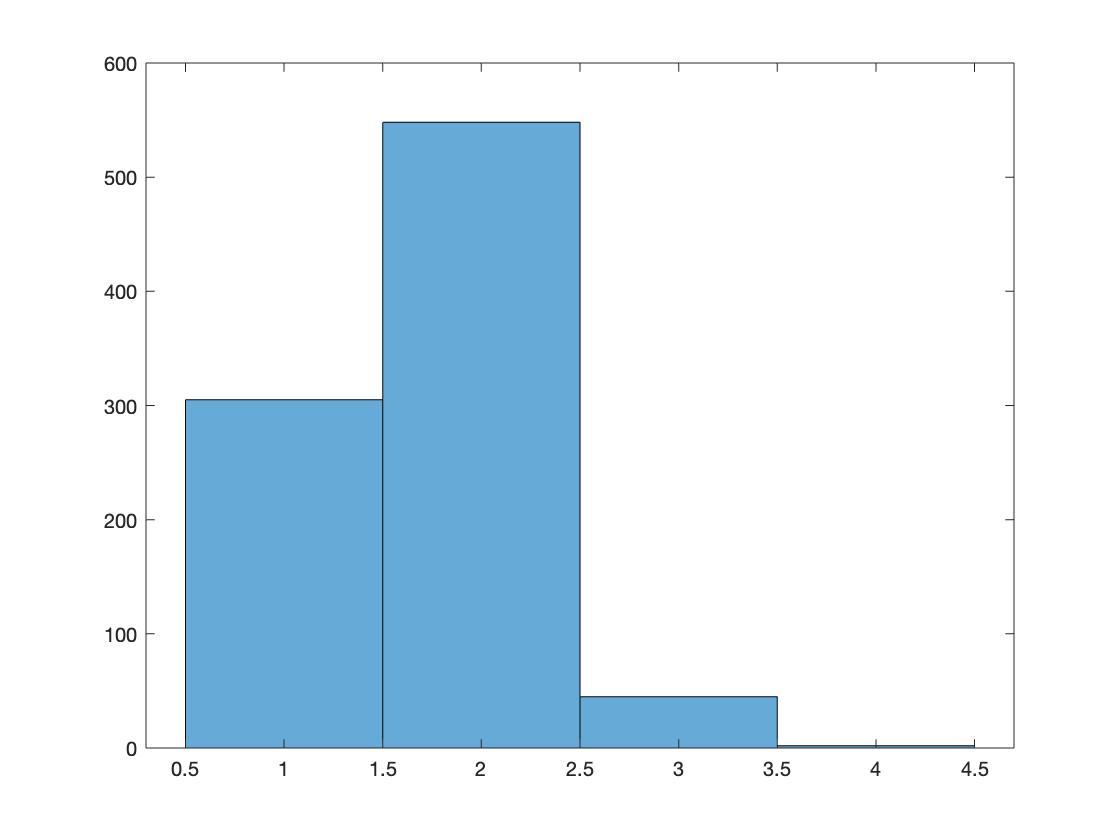

figure
preSD_counts=histogram(states_1h);

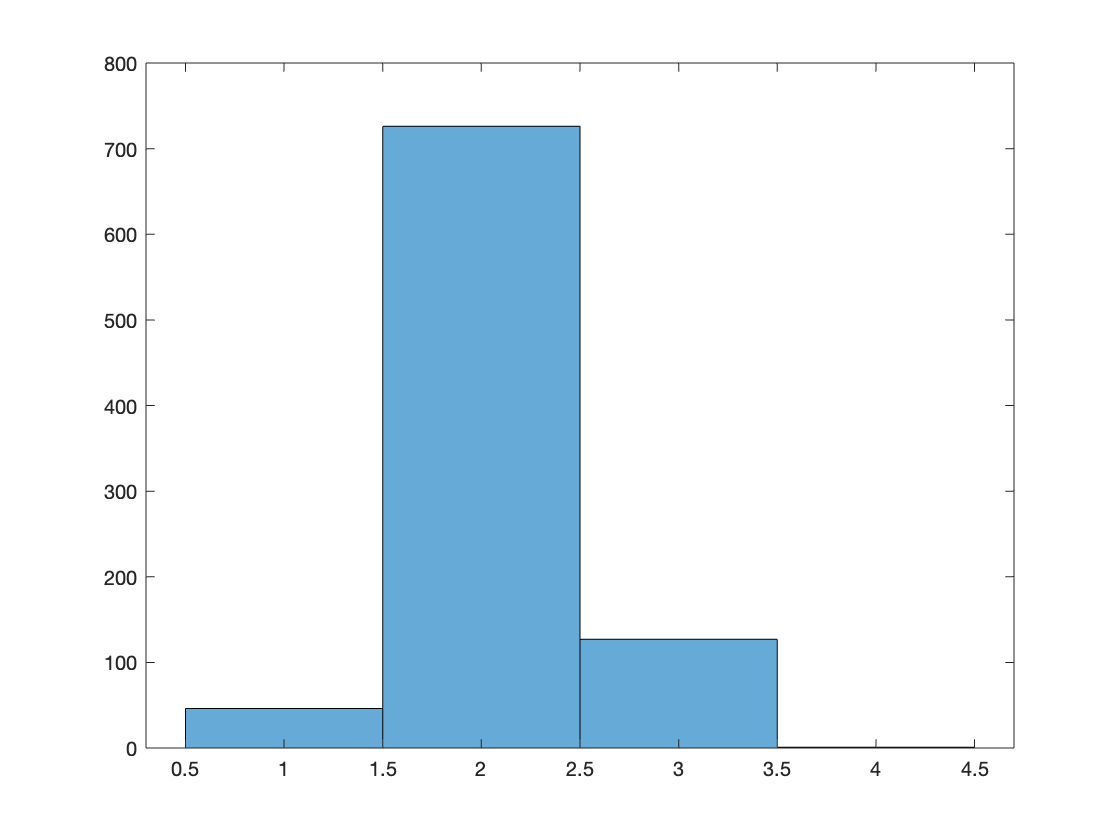


figure
postSD_counts=histogram(states_4h);

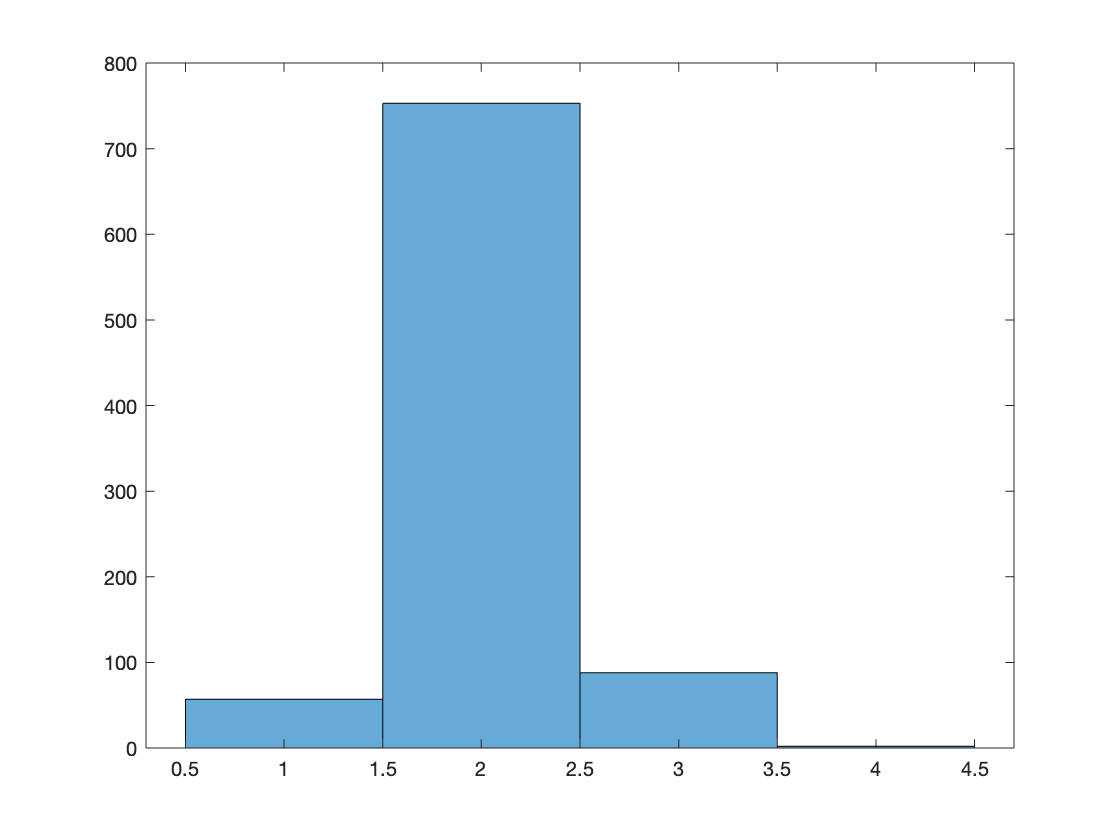


figure
postSD_counts2=histogram(states_5h);

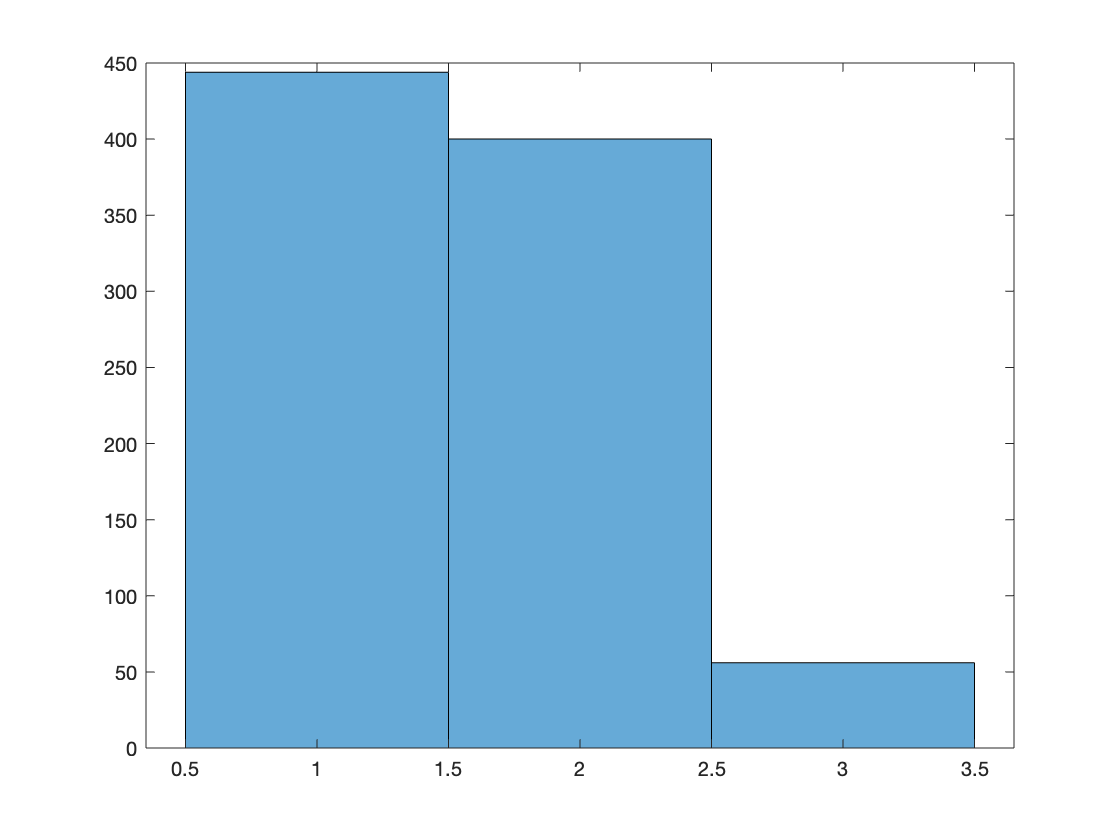


figure
postSD_counts3=histogram(states_6h);

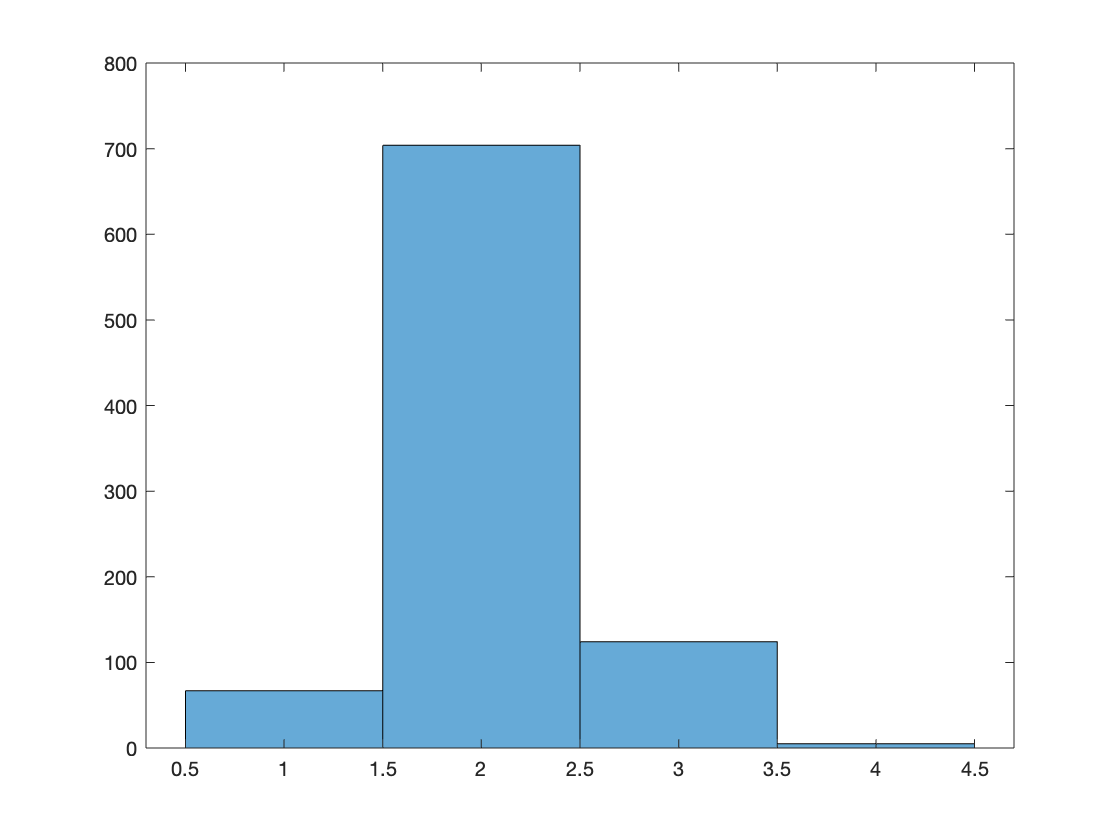


figure
postSD_counts4=histogram(states_7h);

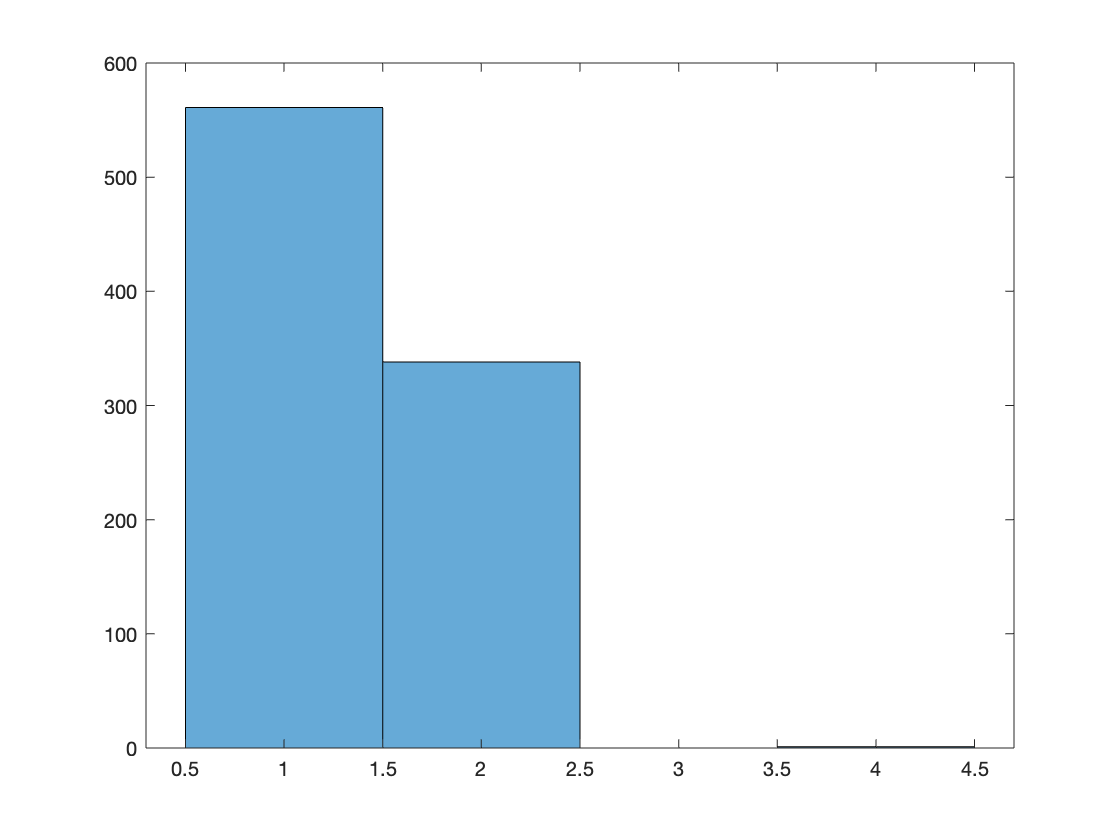


figure
postSD_counts5=histogram(states_8h);


% figure
% postSD_counts6=histogram(states_9h);

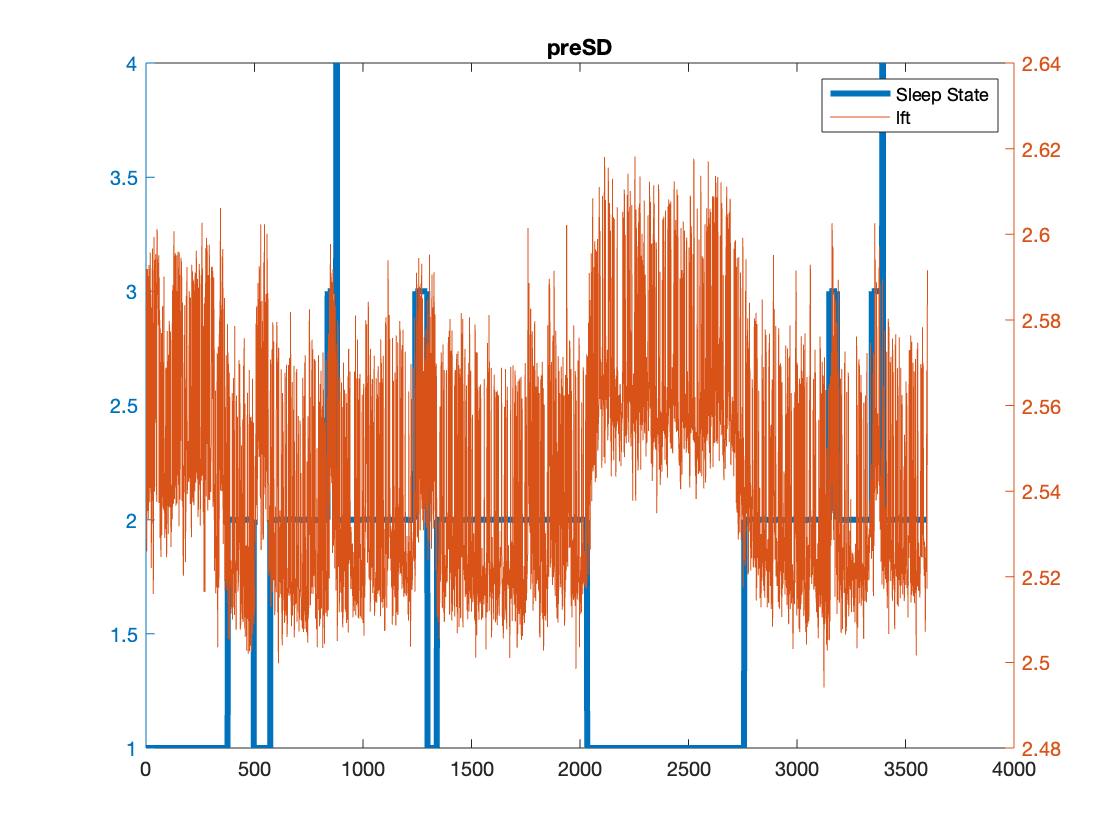

time_for_states=1:1:3600;

figure
yyaxis left
% ScoringHeatMap=heatmap(figure,states_in_seconds_1,'Colormap',[0 1 0;0 0 1;1 0 0;1 1 0],...
%     'GridVisible','off',...
%     'FontColor',[0 0 0],...
%     'ColorLimits',[1 4],...
%     'Title','Scoring (green=wake;blue=NREM;red=REM;yellow=QuietWake)');
% ScoringHeatMap.YDisplayLabels=repmat(' ', 1, 1);
% ScoringHeatMap.XDisplayLabels=repmat(' ', 3600, 1);
plot(time_for_states,states_in_seconds_1, 'lineWidth', 3)
yyaxis right
plot(preSD_time, preSD_tau_empTrunc,'lineWidth', 0.5)
title('preSD')
legend('Sleep State','lft')

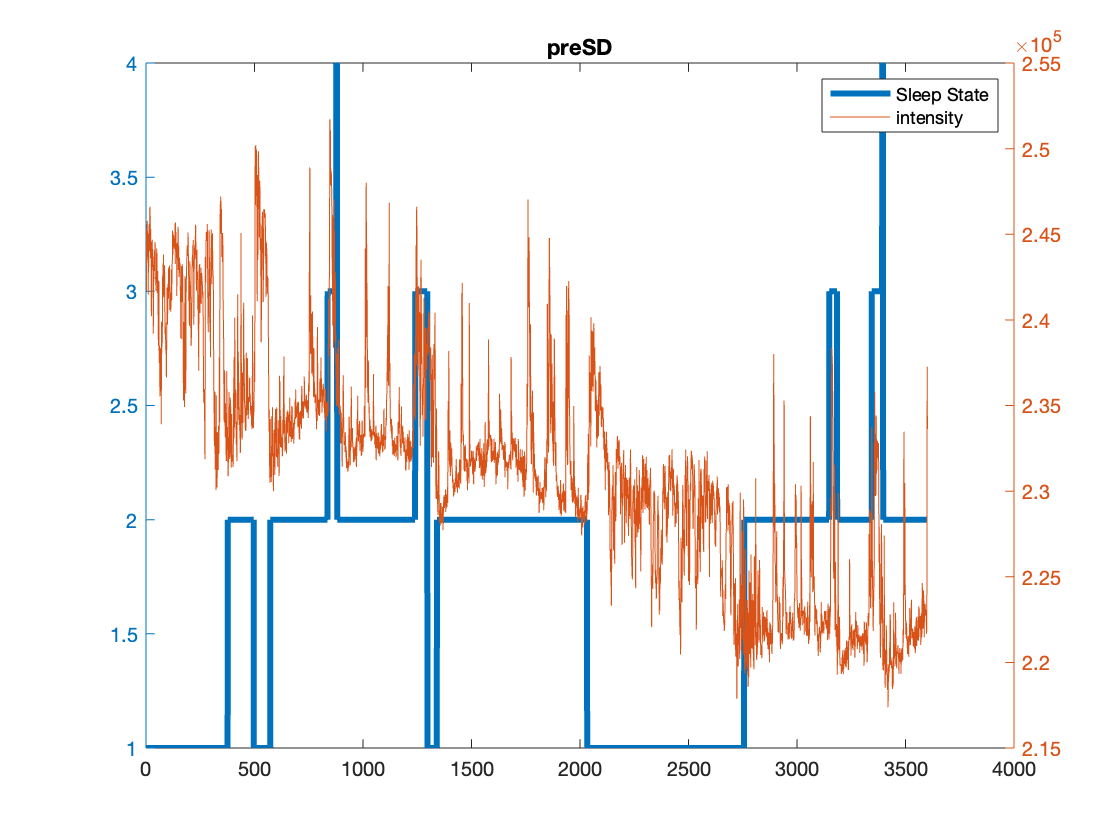


figure
yyaxis left
% ScoringHeatMap=heatmap(figure,states_in_seconds_1,'Colormap',[0 1 0;0 0 1;1 0 0;1 1 0],...
%     'GridVisible','off',...
%     'FontColor',[0 0 0],...
%     'ColorLimits',[1 4],...
%     'Title','Scoring (green=wake;blue=NREM;red=REM;yellow=QuietWake)');
% ScoringHeatMap.YDisplayLabels=repmat(' ', 1, 1);
% ScoringHeatMap.XDisplayLabels=repmat(' ', 3600, 1);
plot(time_for_states,states_in_seconds_1, 'lineWidth', 3)
yyaxis right
plot(preSD_time, preSD_photoncount,'lineWidth', 0.5)
title('preSD')
legend('Sleep State','intensity')

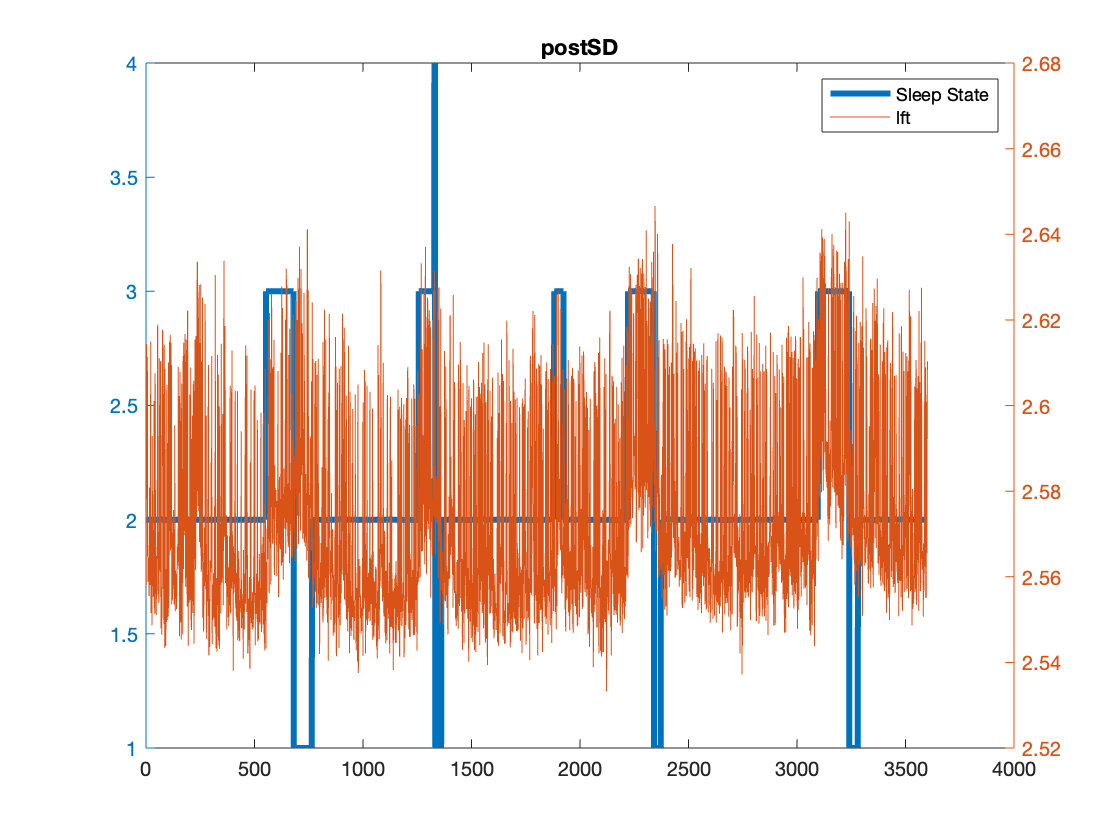

time_for_states=1:1:3600;

figure
yyaxis left
% ScoringHeatMap=heatmap(figure,states_in_seconds_1,'Colormap',[0 1 0;0 0 1;1 0 0;1 1 0],...
%     'GridVisible','off',...
%     'FontColor',[0 0 0],...
%     'ColorLimits',[1 4],...
%     'Title','Scoring (green=wake;blue=NREM;red=REM;yellow=QuietWake)');
% ScoringHeatMap.YDisplayLabels=repmat(' ', 1, 1);
% ScoringHeatMap.XDisplayLabels=repmat(' ', 3600, 1);
plot(time_for_states,states_in_seconds_4, 'lineWidth', 3)
yyaxis right
plot(postSD_time, postSD_tau_empTrunc,'lineWidth', 0.5)
title('postSD')
legend('Sleep State','lft')

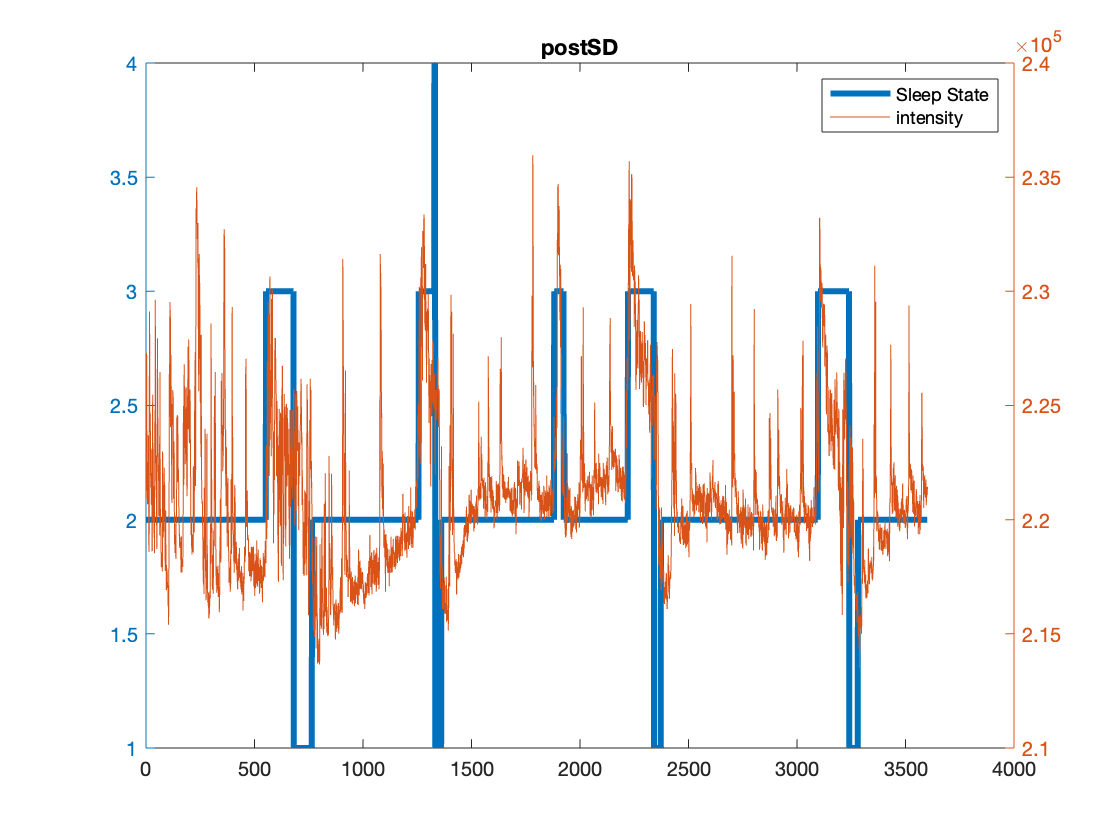


figure
yyaxis left
% ScoringHeatMap=heatmap(figure,states_in_seconds_1,'Colormap',[0 1 0;0 0 1;1 0 0;1 1 0],...
%     'GridVisible','off',...
%     'FontColor',[0 0 0],...
%     'ColorLimits',[1 4],...
%     'Title','Scoring (green=wake;blue=NREM;red=REM;yellow=QuietWake)');
% ScoringHeatMap.YDisplayLabels=repmat(' ', 1, 1);
% ScoringHeatMap.XDisplayLabels=repmat(' ', 3600, 1);
plot(time_for_states,states_in_seconds_4, 'lineWidth', 3)
yyaxis right
plot(postSD_time, postSD_photoncount,'lineWidth', 0.5)
title('postSD')
legend('Sleep State','intensity')


figure
yyaxis left
% ScoringHeatMap=heatmap(figure,states_in_seconds_1,'Colormap',[0 1 0;0 0 1;1 0 0;1 1 0],...
%     'GridVisible','off',...
%     'FontColor',[0 0 0],...
%     'ColorLimits',[1 4],...
%     'Title','Scoring (green=wake;blue=NREM;red=REM;yellow=QuietWake)');
% ScoringHeatMap.YDisplayLabels=repmat(' ', 1, 1);
% ScoringHeatMap.XDisplayLabels=repmat(' ', 3600, 1);
plot(time_for_states,states_in_seconds_1, 'lineWidth', 3)
yyaxis right
plot(preSD_time, preSD_tau_empTrunc,'lineWidth', 0.5)
title('preSD')
legend('Sleep State','lft')

mkdir('csv_1210')


filename='csv_1210/1210_preSD_';

states_serial_csv=[filename,'states.csv'];
time_csv=[filename,'time.csv'];
lft_csv=[filename,'lft.csv'];
lft_DC_csv=[filename,'lft_DC.csv'];

preSD_states=preSD_states';

csvwrite(states_serial_csv,preSD_states);
csvwrite(time_csv,preSD_time);
csvwrite(lft_csv,preSD_tau_empTrunc);
csvwrite(lft_DC_csv,preSD_tau_empTrunc_DC);


filename='csv_1210/1210_FirstHour_';

states_serial_csv=[filename,'states.csv'];
time_csv=[filename,'time.csv'];
lft_csv=[filename,'lft.csv'];
lft_DC_csv=[filename,'lft_DC.csv'];

FirstHour_states=FirstHour_states';

csvwrite(states_serial_csv,FirstHour_states);
csvwrite(time_csv,FirstHour_time);
csvwrite(lft_csv,FirstHour_tau_empTrunc);
csvwrite(lft_DC_csv,FirstHour_tau_empTrunc_DC);


filename='csv_1210/1210_SixthHour_';

states_serial_csv=[filename,'states.csv'];
time_csv=[filename,'time.csv'];
lft_csv=[filename,'lft.csv'];
lft_DC_csv=[filename,'lft_DC.csv'];

SixthHour_states=SixthHour_states';

csvwrite(states_serial_csv,SixthHour_states);
csvwrite(time_csv,SixthHour_time);
csvwrite(lft_csv,SixthHour_tau_empTrunc);
csvwrite(lft_DC_csv,SixthHour_tau_empTrunc_DC);


filename='csv_1210/1210_postSD_';

states_serial_csv=[filename,'states.csv'];
time_csv=[filename,'time.csv'];
lft_csv=[filename,'lft.csv'];
lft_DC_csv=[filename,'lft_DC.csv'];

postSD_states=postSD_states';

csvwrite(states_serial_csv,postSD_states);
csvwrite(time_csv,postSD_time);
csvwrite(lft_csv,postSD_tau_empTrunc);
csvwrite(lft_DC_csv,postSD_tau_empTrunc_DC);